# ODE Visualization Using MATLAB

## Parameters

clear all;
clc;

f = input('Enter your function: ');

x0 = input('Enter initial value of independent variable (x0): ');
y0 = input('Enter initial value of dependent variable (y0): ');
h = input('Enter step size (h): ');
xn = input('Enter point at which you want to evaluate the solution (xn): ');

n = round((xn - x0) / h);

## Euler Method

## 
$$y_{n+1} =y_n \;+h\;f\left(x_{n,} y_n \right)$$


function [x, y] = euler_method(f, x0, y0, h, n)
    x = zeros(1, n+1);
    y = zeros(1, n+1);
    x(1) = x0;
    y(1) = y0;
    for i = 1:n
        y(i + 1) = y(i) + h * f(x(i), y(i));
        x(i + 1) = x0 + i * h;

        fprintf('y(%8.4f) = %10.6f\n',x(i+1),y(i+1))
    end
end

[x_euler, y_euler] = euler_method(f, x0, y0, h, n);

y(  0.0100) =   0.870000
y(  0.0200) =   0.765651
y(  0.0300) =   0.681824
y(  0.0400) =   0.614417
y(  0.0500) =   0.560148
y(  0.0600) =   0.516390
y(  0.0700) =   0.481043
y(  0.0800) =   0.452427
y(  0.0900) =   0.429197
y(  0.1000) =   0.410277
y(  0.1100) =   0.394808
y(  0.1200) =   0.382100
y(  0.1300) =   0.371604
y(  0.1400) =   0.362878
y(  0.1500) =   0.355570
y(  0.1600) =   0.349398
y(  0.1700) =   0.344136
y(  0.1800) =   0.339605
y(  0.1900) =   0.335659
y(  0.2000) =   0.332183


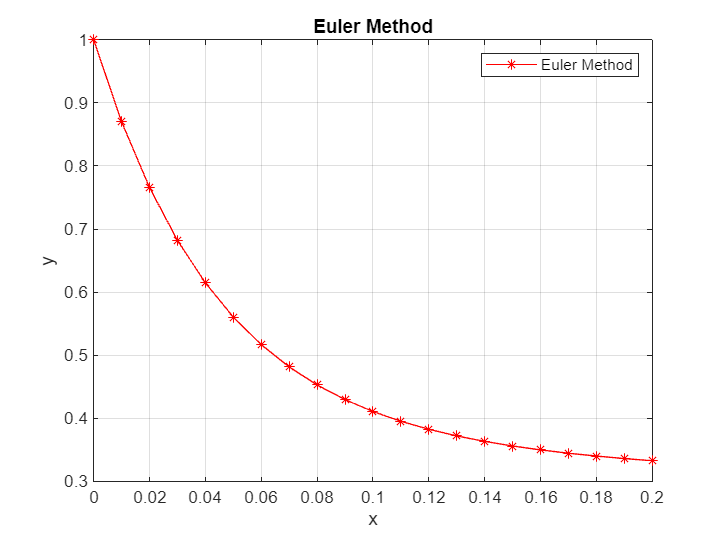

figure;

plot(x_euler, y_euler, 'r-*', 'DisplayName', 'Euler Method');
grid on;
legend('show');
xlabel('x');
ylabel('y');
title('Euler Method');

## Heun's Method

## 
$$\begin{array}{l}
k_1 =h\;f\left(x_n ,y_n \right)\\
k_2 =h\;f\left(x_n +h,y_n +k_1 \right)
\end{array}$$


## 
$$y_{n+1} =y_n +\frac{1}{2}\;\left(k_1 +k_2 \right)$$


function [x, y] = heuns_method(f, x0, y0, h, n)
    x = zeros(1, n+1);
    y = zeros(1, n+1);
    x(1) = x0;
    y(1) = y0;
    for i = 1:n
        k1 = h * f(x(i), y(i));
        k2 = h * f(x(i) + h, y(i) + k1);

        y(i + 1) = y(i) + (1/2) * (k1 + k2);
        x(i + 1) = x0 + i * h;

        fprintf('y(%8.4f) = %10.6f\n',x(i+1),y(i+1))
    end
end

[x_heun, y_heun] = heuns_method(f, x0, y0, h, n);

y(  0.0100) =   0.882825
y(  0.0200) =   0.786429
y(  0.0300) =   0.707072
y(  0.0400) =   0.641689
y(  0.0500) =   0.587767
y(  0.0600) =   0.543243
y(  0.0700) =   0.506428
y(  0.0800) =   0.475935
y(  0.0900) =   0.450629
y(  0.1000) =   0.429577
y(  0.1100) =   0.412014
y(  0.1200) =   0.397315
y(  0.1300) =   0.384965
y(  0.1400) =   0.374543
y(  0.1500) =   0.365703
y(  0.1600) =   0.358163
y(  0.1700) =   0.351689
y(  0.1800) =   0.346091
y(  0.1900) =   0.341212
y(  0.2000) =   0.336926


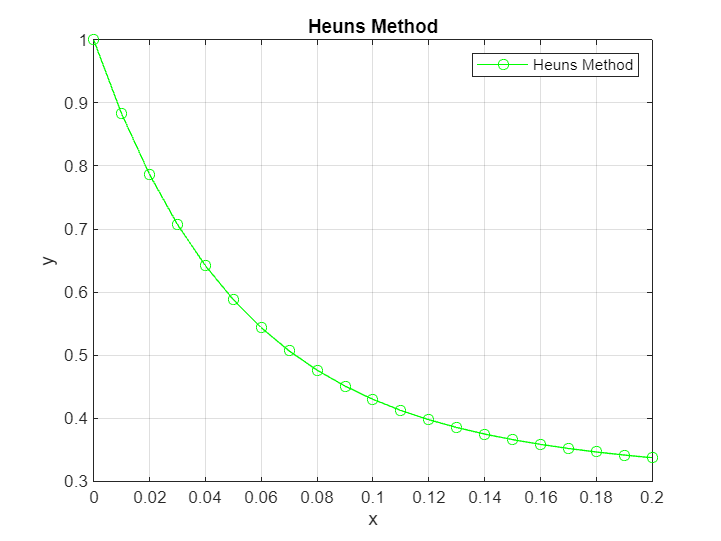

figure;

plot(x_heun, y_heun, 'g-o', 'DisplayName', 'Heuns Method');
grid on;
legend('show');
xlabel('x');
ylabel('y');
title('Heuns Method');

## Midpoint Method

## 
$$\begin{array}{l}
k_1 =h\;f\left(x_n ,y_n \right)\\
k_2 =h\;f\left(x_n +\frac{h}{2},y_n +\frac{k_1 }{2}\right)
\end{array}$$


## 
$$y_{n+1} =y_n +k_2$$


function [x, y] = midpoint_method(f, x0, y0, h, n)
    x = zeros(1, n+1);
    y = zeros(1, n+1);
    x(1) = x0;
    y(1) = y0;
    for i = 1:n
        k1 = f(x(i), y(i));
        k2 = f(x(i) + (h / 2), y(i) + (h / 2) * k1);

        y(i + 1) = y(i) + h * k2;
        x(i + 1) = x0 + i * h;

        fprintf('y(%8.4f) = %10.6f\n',x(i+1),y(i+1))
    end
end

[x_mid, y_mid] = midpoint_method(f, x0, y0, h, n);

y(  0.0100) =   0.882825
y(  0.0200) =   0.786429
y(  0.0300) =   0.707072
y(  0.0400) =   0.641689
y(  0.0500) =   0.587766
y(  0.0600) =   0.543242
y(  0.0700) =   0.506427
y(  0.0800) =   0.475934
y(  0.0900) =   0.450628
y(  0.1000) =   0.429576
y(  0.1100) =   0.412013
y(  0.1200) =   0.397314
y(  0.1300) =   0.384964
y(  0.1400) =   0.374542
y(  0.1500) =   0.365702
y(  0.1600) =   0.358162
y(  0.1700) =   0.351687
y(  0.1800) =   0.346089
y(  0.1900) =   0.341211
y(  0.2000) =   0.336925


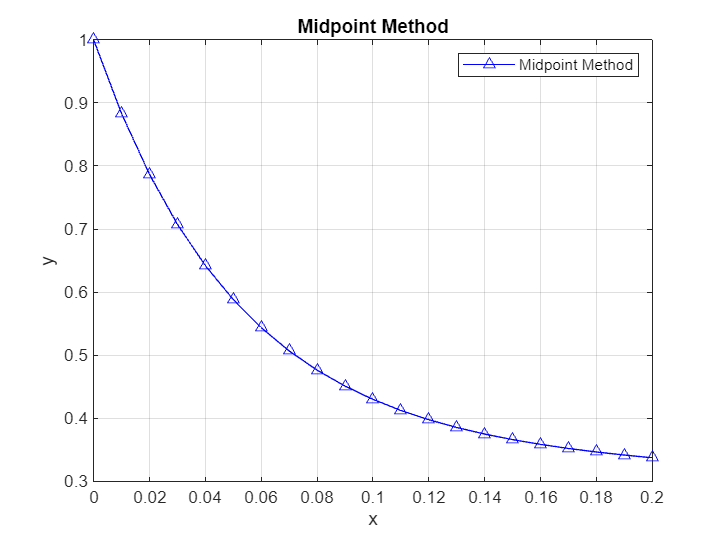

figure;

plot(x_mid, y_mid, 'b-^', 'DisplayName', 'Midpoint Method');
grid on;
legend('show');
xlabel('x');
ylabel('y');
title('Midpoint Method');

## Runge-Kutta Method

## 
$$\begin{array}{l}
k_1 =h\;f\left(x_n ,y_n \right)\\
k_2 =h\;f\left(x_n +\frac{h}{2},y_n +\frac{k_1 }{2}\right)\\
k_3 =h\;f\left(x_n +\frac{h}{2},y_n +\frac{k_2 }{2}\right)\\
k_4 =h\;f\left(x_n +h,y_n +k_3 \right)
\end{array}$$


## 
$$y_{n+1} =y_n +\frac{1}{6}\;\left\lbrack k_1 +2\;k_2 +2\;k_3 +k_4 \right\rbrack$$


function [x, y] = rk_method(f, x0, y0, h, n)
    x = zeros(1, n+1);
    y = zeros(1, n+1);
    x(1) = x0;
    y(1) = y0;
    for i = 1:n
        k1 = h * f(x(i), y(i));
        k2 = h * f(x(i) + (h / 2), y(i) + (k1 / 2));
        k3 = h * f(x(i) + (h / 2), y(i) + (k2 / 2));
        k4 = h * f(x(i) + h, y(i) + k3);

        y(i + 1) = y(i) + (1/6) * (k1 + 2 * k2 + 2 * k3 + k4);
        x(i + 1) = x0 + i * h;

        fprintf('y(%8.4f) = %10.6f\n',x(i+1),y(i+1))
    end
end

[x_rk, y_rk] = rk_method(f, x0, y0, h, n);

y(  0.0100) =   0.882013
y(  0.0200) =   0.785098
y(  0.0300) =   0.705436
y(  0.0400) =   0.639901
y(  0.0500) =   0.585935
y(  0.0600) =   0.541442
y(  0.0700) =   0.504706
y(  0.0800) =   0.474323
y(  0.0900) =   0.449142
y(  0.1000) =   0.428223
y(  0.1100) =   0.410794
y(  0.1200) =   0.396224
y(  0.1300) =   0.383996
y(  0.1400) =   0.373688
y(  0.1500) =   0.364952
y(  0.1600) =   0.357506
y(  0.1700) =   0.351117
y(  0.1800) =   0.345594
y(  0.1900) =   0.340783
y(  0.2000) =   0.336555


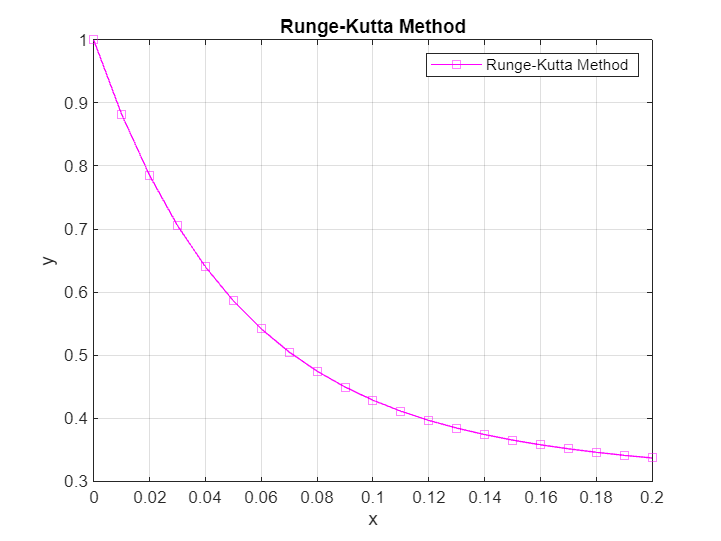

figure;

plot(x_rk, y_rk, 'm-s', 'DisplayName', 'Runge-Kutta Method');
grid on;
legend('show');
xlabel('x');
ylabel('y');
title('Runge-Kutta Method');

## Real solution of ODE

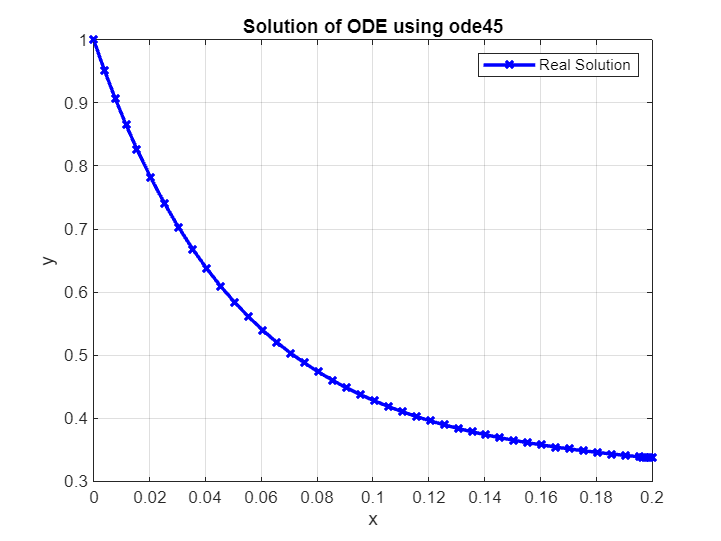

[x, y] = ode45(f, [x0 xn], y0);

figure;
plot(x, y, 'b-x', 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('y');
title('Solution of ODE using ode45');
legend('Real Solution');

## Comparison of ODE Solution Methods

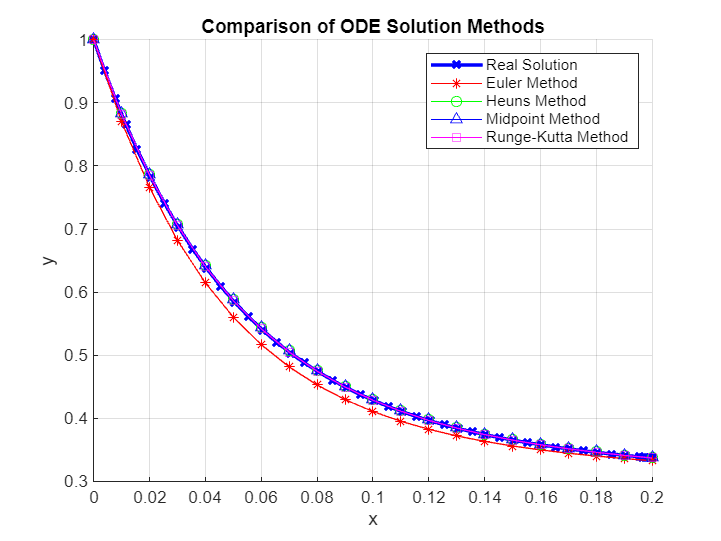

figure;
hold on
plot(x, y, 'b-x', 'LineWidth', 2, 'DisplayName', 'Real Solution');
plot(x_euler, y_euler, 'r-*', 'DisplayName', 'Euler Method');
plot(x_heun, y_heun, 'g-o', 'DisplayName', 'Heuns Method');
plot(x_mid, y_mid, 'b-^', 'DisplayName', 'Midpoint Method');
plot(x_rk, y_rk, 'm-s', 'DisplayName', 'Runge-Kutta Method');
grid on;
legend('show');
xlabel('x');
ylabel('y');
title('Comparison of ODE Solution Methods');
hold off;

## Accuracy

relative_error_euler = abs((y_euler - interp1(x, y, x_euler)) ./ interp1(x, y, x_euler)) * 100;
relative_error_heun = abs((y_heun - interp1(x, y, x_heun)) ./ interp1(x, y, x_heun)) * 100;
relative_error_mid = abs((y_mid - interp1(x, y, x_mid)) ./ interp1(x, y, x_mid)) * 100;
relative_error_rk = abs((y_rk - interp1(x, y, x_rk)) ./ interp1(x, y, x_rk)) * 100;

fprintf('Accuracy of Euler Method: %.2f%%\n', 100 - mean(relative_error_euler));

Accuracy of Euler Method: 96.99%


fprintf('Accuracy of Heun''s Method: %.2f%%\n', 100 - mean(relative_error_heun));

Accuracy of Heun's Method: 99.78%


fprintf('Accuracy of Midpoint Method: %.2f%%\n', 100 - mean(relative_error_mid));

Accuracy of Midpoint Method: 99.78%


fprintf('Accuracy of Runge-Kutta Method: %.2f%%\n', 100 - mean(relative_error_rk));

Accuracy of Runge-Kutta Method: 99.99%
